clear

AR = 8.5;
Sweep = 0;
Taper = 0.93;
c_bar = 3.54;
srefref = 101;
fuselage_rad = 1.25;
twist = -3*pi/180;
panelnum = 100;
Uinf = 1;

incidence = 1*pi/180;


airfoil(1).Field = 'root';
airfoil(1).alpha0 = -0.07;
airfoil(1).a = 6.68;
airfoil(2).Field = 'tip';
airfoil(2).alpha0 = -0.07;
airfoil(2).a = 6.68;


%% discritize planform to plot
[Sref, c_y, span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)

Sref = 106.4855

c_y =     3.6678    3.6677    3.6675    3.6673    3.6671    3.6670    3.6668    3.6666    3.6665    3.6663    3.6661    3.6659    3.6658    3.6656    3.6654    3.6653    3.6651    3.6649    3.6648    3.6646    3.6644    3.6642    3.6641    3.6639    3.6637    3.6636    3.6634    3.6632    3.6630    3.6629    3.6627    3.6625    3.6624    3.6622    3.6620    3.6618    3.6617    3.6615    3.6613    3.6612    3.6610    3.6608    3.6607    3.6605    3.6603    3.6601    3.6600    3.6598    3.6596    3.6595


span_disc =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


quarterchord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


MACpos = 750


semispan = length(span_disc)*0.01

semispan = 15.0500


thetadist = acos(span_disc/span_disc(end))

thetadist =     1.5708    1.5701    1.5695    1.5688    1.5681    1.5675    1.5668    1.5661    1.5655    1.5648    1.5641    1.5635    1.5628    1.5622    1.5615    1.5608    1.5602    1.5595    1.5588    1.5582    1.5575    1.5568    1.5562    1.5555    1.5548    1.5542    1.5535    1.5528    1.5522    1.5515    1.5508    1.5502    1.5495    1.5489    1.5482    1.5475    1.5469    1.5462    1.5455    1.5449    1.5442    1.5435    1.5429    1.5422    1.5415    1.5409    1.5402    1.5395    1.5389    1.5382



twist_dis = linspace(0,twist,length(span_disc))

twist_dis =          0   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0010   -0.0010   -0.0010   -0.0011   -0.0011   -0.0011   -0.0012   -0.0012   -0.0013   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0015   -0.0015   -0.0015   -0.0016   -0.0016   -0.0016   -0.0017   -0.0017


alpha_0_dis = linspace(airfoil(1).alpha0,airfoil(2).alpha0,length(span_disc))

alpha_0_dis =    -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700


incidence_dis = incidence*ones(1,length(span_disc))

incidence_dis =     0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175


alpha_dis = twist_dis - alpha_0_dis + incidence_dis

alpha_dis =     0.0875    0.0874    0.0874    0.0873    0.0873    0.0873    0.0872    0.0872    0.0872    0.0871    0.0871    0.0871    0.0870    0.0870    0.0870    0.0869    0.0869    0.0869    0.0868    0.0868    0.0868    0.0867    0.0867    0.0867    0.0866    0.0866    0.0865    0.0865    0.0865    0.0864    0.0864    0.0864    0.0863    0.0863    0.0863    0.0862    0.0862    0.0862    0.0861    0.0861    0.0861    0.0860    0.0860    0.0860    0.0859    0.0859    0.0859    0.0858    0.0858    0.0857



a_dis = linspace(airfoil(1).a,airfoil(2).a,length(span_disc))

a_dis =     6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800



mu_dis = (a_dis.*c_y)/(4.*AR*c_bar)

mu_dis =     0.2036    0.2036    0.2035    0.2035    0.2035    0.2035    0.2035    0.2035    0.2035    0.2035    0.2035    0.2035    0.2035    0.2034    0.2034    0.2034    0.2034    0.2034    0.2034    0.2034    0.2034    0.2034    0.2034    0.2033    0.2033    0.2033    0.2033    0.2033    0.2033    0.2033    0.2033    0.2033    0.2033    0.2033    0.2032    0.2032    0.2032    0.2032    0.2032    0.2032    0.2032    0.2032    0.2032    0.2032    0.2031    0.2031    0.2031    0.2031    0.2031    0.2031



LHS = zeros(floor(panelnum/2),1);
RHS = zeros(floor(panelnum/2),floor(panelnum/2));

for i = 1:floor(panelnum/2)
    for j = 1 : floor(panelnum/2)
%         tempind = floor((i*length(span_disc)/panelnum - length(span_disc)/(2*panelnum)));
        [temp,tempind]= min(abs(thetadist-i*pi/panelnum));
        LHS(i,1) = mu_dis(tempind)*alpha_dis(tempind)*sin(thetadist(tempind));
        RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
    end
end
Aseries = RHS\LHS;
gamma_span_coef = 4*semispan*Uinf;
gamma_sum = 0;

for n = 1:floor(panelnum/2)
    gamma_sum = gamma_sum + Aseries(n)*sin(n*thetadist);
end

gamma_plot = gamma_span_coef*gamma_sum

gamma_plot =     0.7110    0.7110    0.7110    0.7109    0.7109    0.7109    0.7108    0.7108    0.7108    0.7107    0.7107    0.7106    0.7106    0.7106    0.7105    0.7105    0.7105    0.7104    0.7104    0.7103    0.7103    0.7103    0.7102    0.7102    0.7102    0.7101    0.7101    0.7100    0.7100    0.7100    0.7099    0.7099    0.7098    0.7098    0.7097    0.7097    0.7097    0.7096    0.7096    0.7095    0.7095    0.7094    0.7094    0.7094    0.7093    0.7093    0.7092    0.7092    0.7091    0.7091


gamma_ellipse = 4*semispan*Uinf*Aseries(1)*sin(thetadist)

gamma_ellipse =     0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7399    0.7398    0.7398    0.7398    0.7398    0.7398    0.7398    0.7398    0.7398    0.7398    0.7397    0.7397    0.7397    0.7397    0.7397    0.7397    0.7397    0.7396    0.7396    0.7396    0.7396    0.7396


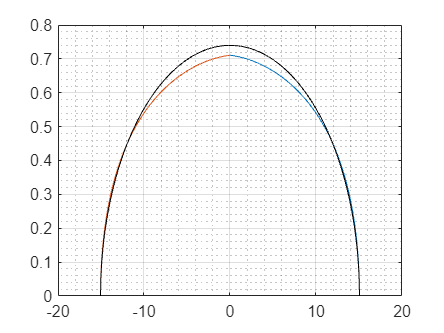

plot(semispan*cos(thetadist),gamma_plot)
hold on
plot(-semispan*cos(thetadist),gamma_plot)

plot(-semispan*cos(thetadist),gamma_ellipse,'k')
plot(semispan*cos(thetadist),gamma_ellipse,'k')

grid on
grid minor


hold off


MACcord = span_disc(MACpos)

MACcord = 7.4900

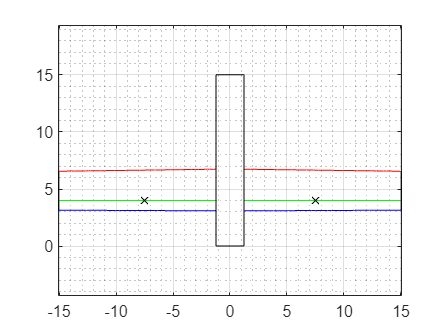

longitudinalMACac =  4;
fuselagedatum = 0;
feselageend = 15;


% plot(span_disc,c_y,'.')
% x_engine = quarterchord(ceil(length(c_y)*0.37))
% height_engine0.37*max(span_disc)*tand(5)-0.175*c_y(ceil(length(c_y)*0.37))-0.9
LEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) - 0.25 .* c_y;
TEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) + 0.75 .* c_y;
quarterchordplot = (quarterchord-quarterchord(MACpos) + longitudinalMACac);
%origin at quarterchord point of root chord
plot (span_disc(fuselage_rad*100:end),LEsweep(fuselage_rad*100:end),'b')
hold on
plot (span_disc(fuselage_rad*100:end),TEsweep(fuselage_rad*100:end),'r')
plot (span_disc(fuselage_rad*100:end),quarterchordplot(fuselage_rad*100:end),'g')
plot (span_disc(MACpos),quarterchordplot(MACpos),'xk')

plot (-span_disc(fuselage_rad*100:end),TEsweep(fuselage_rad*100:end),'r')
hold on
plot (-span_disc(fuselage_rad*100:end),LEsweep(fuselage_rad*100:end),'b')
plot (-span_disc(fuselage_rad*100:end),quarterchordplot(fuselage_rad*100:end),'g')
plot (-span_disc(MACpos),quarterchordplot(MACpos),'xk')

plot ([span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)], [LEsweep(fuselage_rad*100),TEsweep(fuselage_rad*100)],'k')
plot ([span_disc(end),span_disc(end)], [LEsweep(end),TEsweep(end)],'k')
plot ([-span_disc(fuselage_rad*100),-span_disc(fuselage_rad*100)], [LEsweep(fuselage_rad*100),TEsweep(fuselage_rad*100)],'k')
plot ([-span_disc(end),-span_disc(end)], [LEsweep(end),TEsweep(end)],'k')

plot ([span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuselage_rad*100),-span_disc(fuselage_rad*100)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[fuselagedatum,fuselagedatum],'k')
plot ([-span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[feselageend,feselageend],'k')

ylim([-7.5 7.5])
axis equal
hold off
grid on
grid minor

chordpos = 0;



function [Sref, c_y,span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)
s_1 = 0.25 * AR * (1+Taper); %_1 using 1 as reference root chord length
Sref_1 = (1 + Taper) * s_1;
span_disc_1 = [0:0.01:s_1];
c_y_1 = 1 - ((1-Taper)/s_1) * span_disc_1;
c_bar_1 = 2*trapz(span_disc_1,(c_y_1).^2)/Sref_1;
ratio = c_bar/c_bar_1; % dimensionalize using c_bar, can be changed later to root or tip chord length
s = ratio*s_1;
Sref = ratio * (1 + Taper) * s;
span_disc = [0:0.01:s];
c_y =  (1 - ((1-Taper)/s) * span_disc)*ratio;
temp1 = (c_y - c_bar).^2;
MACpos = find(temp1 == min(temp1));
quarterchord =  span_disc .* tand(Sweep);
end